# Use the model to remove exogenous fluorophores

This routine is applied to the full 500-700 nm range.

We use the savedFluorophores estimated in Figure 5 to model the data from external sources (e.g., de Veld).  We show that the model can fit those data. 

We then use the fits to separate out the porphyrins and chlorophyll-a from the signal, leaving the endogenous fluorophores (collagen-blood, FAD, and keratin).  Plotting those curves shows that the population is rather compact.

## oeSolveBlood

This takes in the five saved fluorophores and estimates the amount of blood we need to apply to the collagen to get a fit.

We identify the components of the endogenous fluorophores from the fit and plot those separately.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = {'Z','B','D','J'};
[T,dataDir] = oeDatabaseCreate;

## Read the saved model fluorophores

These have no blood.  The blood will be read in during the fitting process with oeSolveBlood.

fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
[savedFluorophores,~,comment] = ieReadSpectra(fname,wave);

To see the saved fluorophores including keratin (no blood)

## Read the external data

veldCheek  = ieReadSpectra('CheekVeld2003.mat',wave); 
veldCheek  = veldCheek/veldCheek(wave == 520);
veldTongue = ieReadSpectra('TongueVeld2003.mat',wave);
veldTongue  = veldTongue/veldTongue(wave == 520);

## Fit the model to deVeld tongue data

[odT,weightsT,finalFluorophoresT] = oeSolveBlood(wave,veldTongue,savedFluorophores);

If you want to see the fluorophores with blood, run this

predictedT = finalFluorophoresT*weightsT(:);
ieFigure;
plot(wave,predictedT,'k--',wave,veldTongue,'k-');
grid on;
title(sprintf('de Veld tongue (od = %.3f)',odT));


Separate out the endogenous from the exogenous

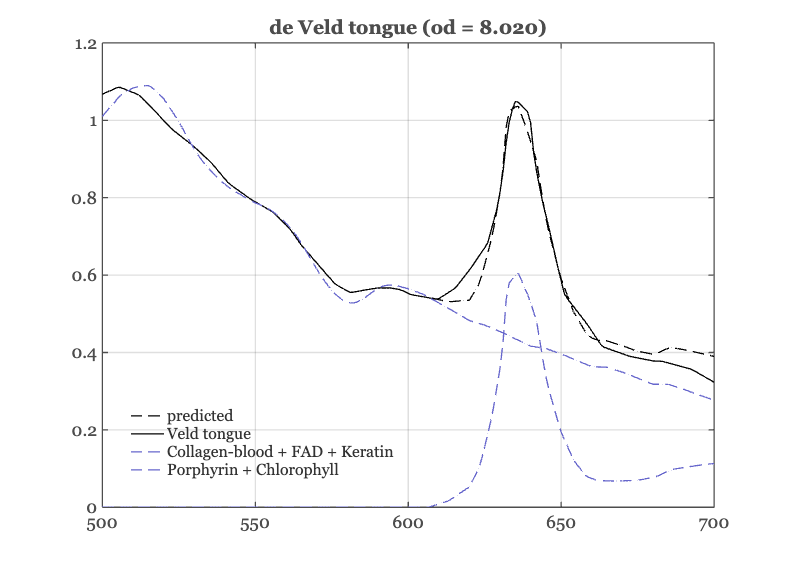

endogenousT = finalFluorophoresT(:,[1:2,5])*weightsT([1:2,5]);
exogenousT = finalFluorophoresT(:,3:4)*weightsT(3:4);
hold on;
plot(wave,endogenousT,'--','Color',[0.4 0.4 0.8]);
plot(wave,exogenousT,'--','Color',[0.4 0.4 0.8]);
legend(["predicted", "Veld tongue", "Collagen-blood + FAD + Keratin", "Porphyrin + Chlorophyll"], "Position", [0.1602 0.1563 0.3445, 0.1342])

% legend(["predicted", "Veld tongue", "Collagen-blood + FAD + Keratin", "Porphyrin + Chlorophyll"]);


## Fit the cheek

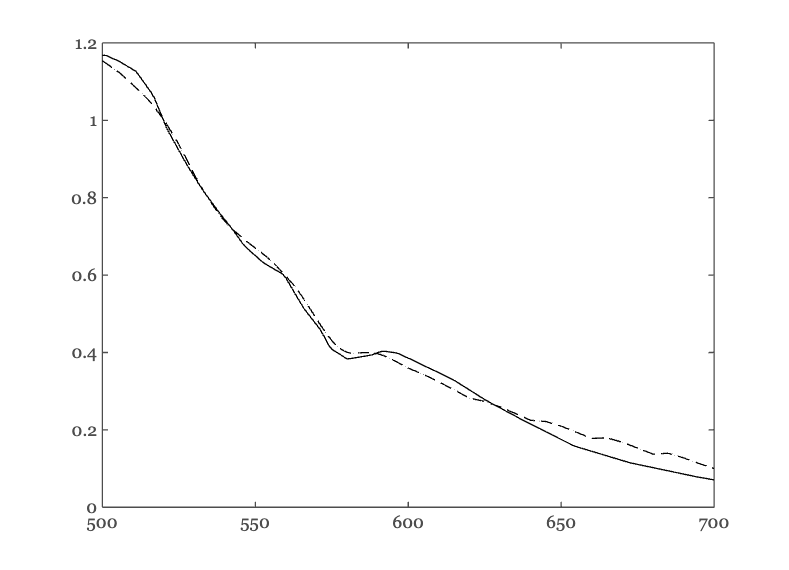

[odC,weightsC,finalFluorophoresC] = oeSolveBlood(wave,veldCheek,savedFluorophores(:,1:2));
predictedC = finalFluorophoresC*weightsC(:);
ieFigure;
plot(wave,predictedC,'k--',wave,veldCheek,'k-'); hold on;

% odT is a scalar value
% weightsT is a numerical array with 5 elements

% Define the labels
labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};

% Combine the values into a single array
% This assumes weightsT is a row or column vector of 5 elements
values = [odT; weightsT(:)]; % Use (:) to ensure weightsT is a column vector for concatenation

% Determine the maximum label width for alignment
maxLabelWidth = max(cellfun(@length, labels));

% fprintf('%*s  Value\n', maxLabelWidth, 'Component'); % Use dynamic width
% fprintf('%s\n', repmat('-', maxLabelWidth + 8, 1)); % Print a separator line

% Print each row of the table
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Tongue\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Tongue


         Blood  8.02
Collagen-blood  7.48
           FAD  0.59
     Porphyrin  0.60
 Chlorophyll-a  0.00
       Keratin  0.30


labels = {'Blood', 'Collagen-blood', 'FAD'};
values = [odC; weightsC(:)]; % Use (:) to ensure weightsT is a column vector for concatenation

% Print each row of the table
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Cheek\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Cheek


         Blood  1.71
Collagen-blood  8.50
           FAD  0.47


## Load the  tongue data

Here, we load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.  We fit these to find the pseudo-keratin.

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end


tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end

## Show the predictions for the tongue data

These are the 405 nm and 415 nm fits.

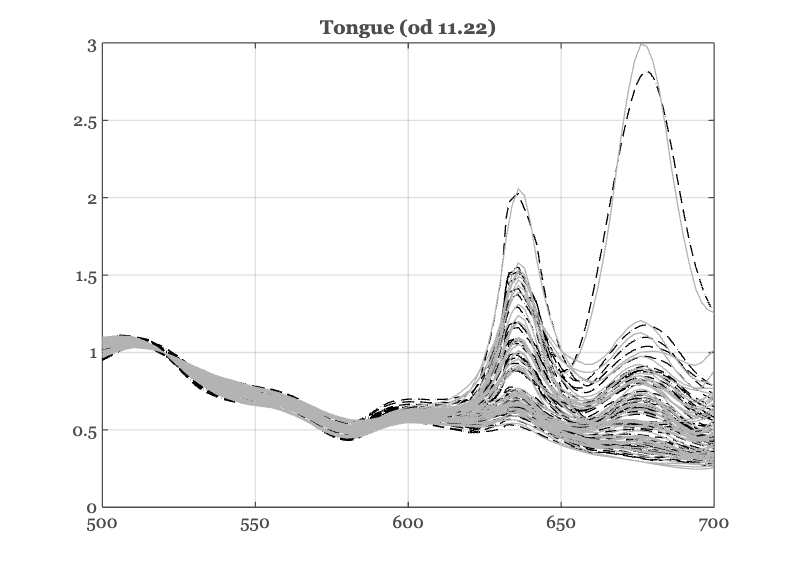

[od,weights,finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
predicted = finalFluorophores*weights;

ieFigure; 
plot(wave,predicted,'k--'); hold on;
plot(wave,tongueData,'Color',[1 1 1]*0.7); 
grid on; title(sprintf('Tongue (od %0.2f)',od));

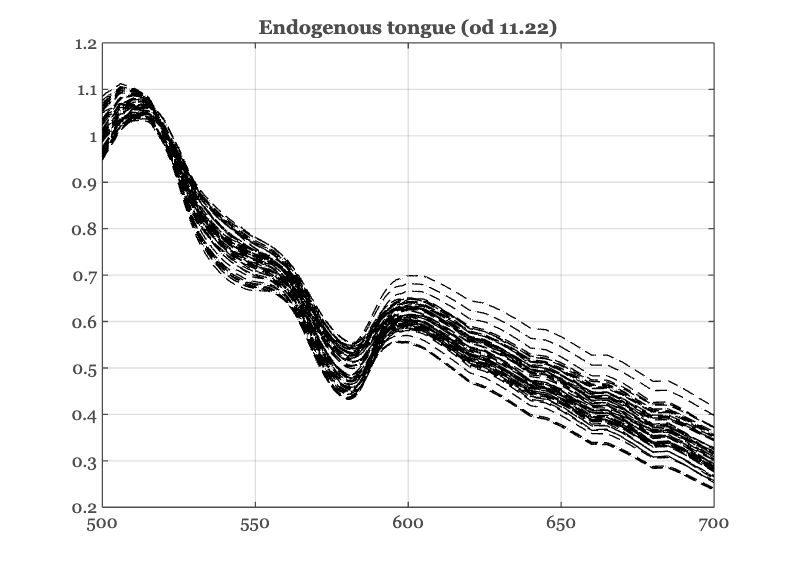

flist = [1 2 5];  % Collagen, FAD, Keratin
endogenous = finalFluorophores(:,flist)*weights(flist,:);
endogenousM405 = mean(endogenous,2);

ieFigure; 
plot(wave,endogenous,'k--'); hold on;
grid on; title(sprintf('Endogenous tongue (od %0.2f)',od));

## Now the 450nm data

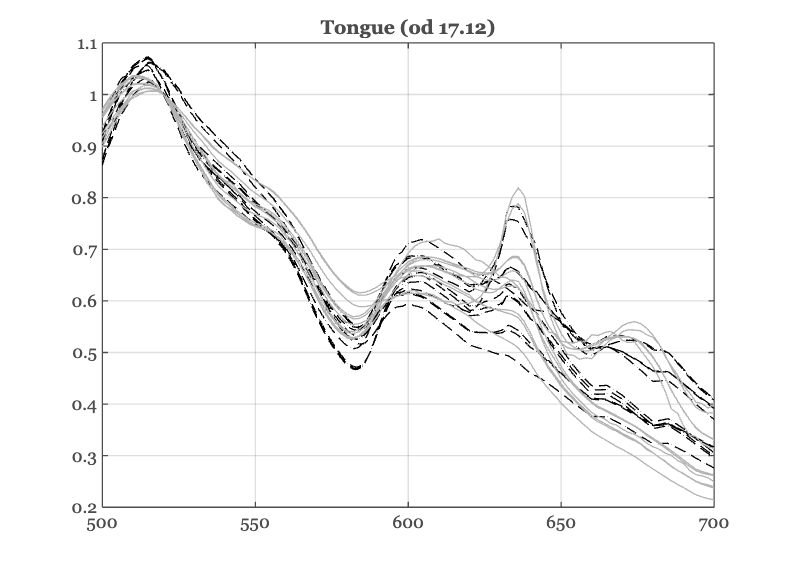

[od,weights,finalFluorophores] = oeSolveBlood(wave,tongueData450,savedFluorophores);
predicted = finalFluorophores*weights;

ieFigure; 
plot(wave,predicted,'k--'); hold on;
plot(wave,tongueData450,'Color',[1 1 1]*0.7); 
grid on; title(sprintf('Tongue (od %0.2f)',od));

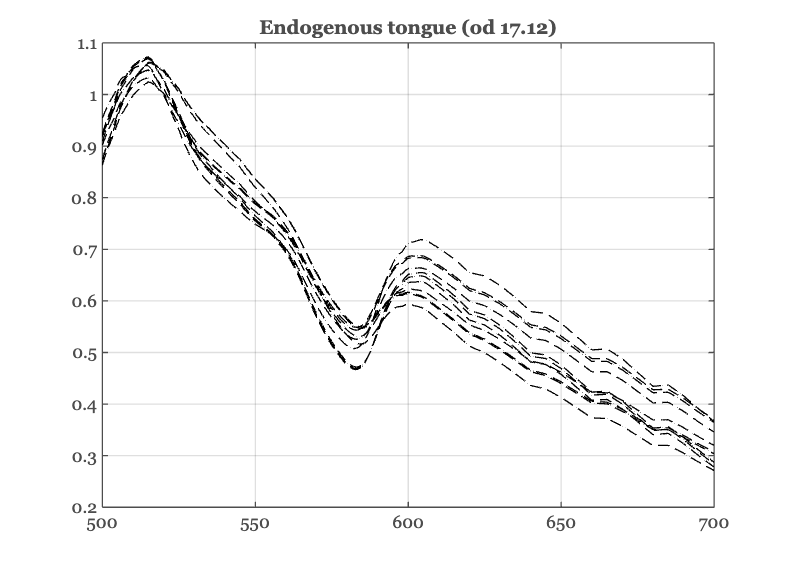

flist = [1 2 5];  % Collagen, FAD, Keratin
endogenous = finalFluorophores(:,flist)*weights(flist,:);
endogenousM450 = mean(endogenous,2);

ieFigure; 
plot(wave,endogenous,'k--'); hold on;
grid on; title(sprintf('Endogenous tongue (od %0.2f)',od));

## Compare the mean endogenous tongue estimates for the 405 vs. 450 excitation lights

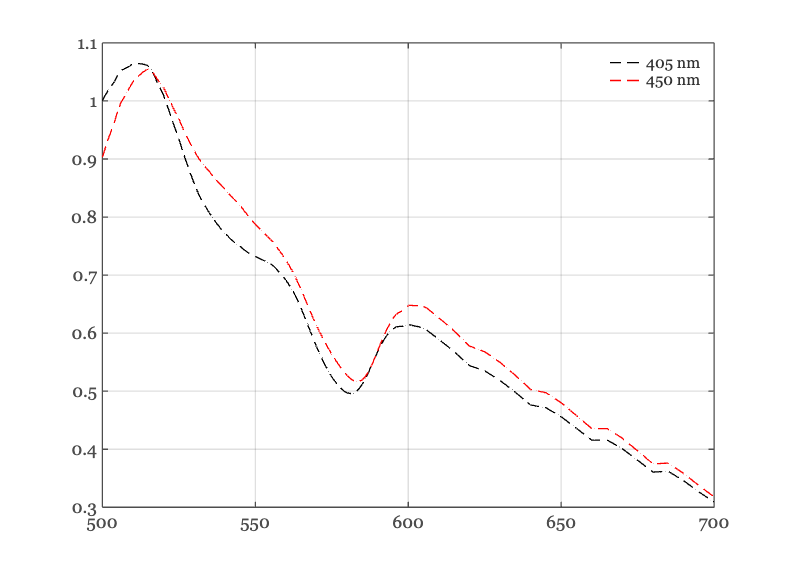

ieFigure;
plot(wave,endogenousM405,'k--',wave,endogenousM450,'r--'); grid on;
legend({'405 nm','450 nm'});

[od,weights] = oeSolveBlood(wave,endogenousM405,savedFluorophores);
[od450,weights450] = oeSolveBlood(wave,endogenousM450,savedFluorophores);

fprintf('Blood 405:  %0.2f\nBlood 450:  %0.2f\n',od,od450);

Blood 405:  11.22
Blood 450:  17.12


fprintf('Tongue 405 weights %0.2f\n',weights([1,2,5]));

Tongue 405 weights 10.42
Tongue 405 weights 0.54
Tongue 405 weights 0.30


fprintf('Tongue 450 weights %0.2f\n',weights450([1,2,5]));

Tongue 450 weights 11.53
Tongue 450 weights 0.66
Tongue 450 weights 0.30
